%% Acoustic Scene Recognition Using Late Fusion
% This example shows how to create a multi-model late fusion system for
% acoustic scene recognition. The example trains a convolutional neural
% network (CNN) using mel spectrograms and an ensemble classifier using
% wavelet scattering. The example uses the TUT dataset for training and
% evaluation [1].

% Copyright 2019 The MathWorks, Inc.

%% Introduction
% Acoustic scene classification (ASC) is the task of classifying
% environments from the sounds they produce. ASC is a generic
% classification problem that is foundational for context awareness in
% devices, robots, and many other applications [1]. Early attempts at ASC
% used mel-frequency cepstral coefficients
% (<docid:audio_ref#mw_b965edcf-ff08-417b-992c-b7f6471536c8 |mfcc|>) and
% Gaussian mixture models (GMMs) to describe their statistical
% distribution. Other popular features used for ASC include zero crossing
% rate, spectral centroid
% (<docid:audio_ref#mw_8322ae3a-5199-42e2-b2a8-a74d0d00cb99
% |spectralCentroid|>), spectral rolloff
% (<docid:audio_ref#mw_f6629b90-7ed3-446f-9c1e-c8400a2142f9
% |spectralRolloffPoint|>), spectral flux
% (<docid:audio_ref#mw_5cdc319c-4260-4d4e-84c5-0712fd2f0dc7 |spectralFlux|>
% ), and linear prediction coefficients (<docid:signal_ref#f7-1093 |lpc|>)
% [5]. Hidden Markov models (HMMs) were trained to describe the temporal
% evolution of the GMMs. More recently, the best performing systems have
% used deep learning, usually CNNs, and a fusion of multiple models. The
% most popular feature for top-ranked systems in the DCASE 2017 contest was
% the mel spectrogram
% (<docid:audio_ref#mw_1bb316de-8018-4365-a351-73374473237f
% |melSpectrogram|>). The top-ranked systems in the challenge used late
% fusion and data augmentation to help their systems generalize.
% 
% To illustrate a simple approach that produces reasonable results, this
% example trains a CNN using mel spectrograms and an ensemble classifier
% using wavelet scattering. The CNN and ensemble classifier produce roughly
% equivalent overall accuracy, but perform better at distinguishing
% different acoustic scenes. To increase overall accuracy, you merge the
% CNN and ensemble classifier results using late fusion.

%% Load Acoustic Scene Recognition Data Set
% To run the example, you must first download the data set [1]. The full
% data set is approximately 15.5 GB. Depending on your machine and internet
% connection, downloading the data can take about 4 hours.

downloadFolder = tempdir;
datasetFolder = fullfile(downloadFolder,'scenes_stereo');

%% 
% Read in the development set metadata as a table. Name the table variables 
% |FileName|, |AcousticScene|.

metadata_train = readtable("dataset.txt");
head(metadata_train)

ans = 8×2 table
                    FileName                     AcousticScene
    _________________________________________    _____________

    {'scenes_stereo/scenes_stereo/bus01.wav'}       {'bus'}   
    {'scenes_stereo/scenes_stereo/bus02.wav'}       {'bus'}   
    {'scenes_stereo/scenes_stereo/bus03.wav'}       {'bus'}   
    {'scenes_stereo/scenes_stereo/bus04.wav'}       {'bus'}   
    {'scenes_stereo/scenes_stereo/bus05.wav'}       {'bus'}   
    {'scenes_stereo/scenes_stereo/bus06.wav'}       {'bus'}   
    {'scenes_stereo/scenes_stereo/bus07.wav'}       {'bus'}   
    {'scenes_stereo/scenes_stereo/bus08.wav'}       {'bus'}   



metadata_test = readtable("dataset_test.txt");
head(metadata_test)

ans = 8×2 table
                        FileName                        AcousticScene 
    ________________________________________________    ______________

    {'scenes_stereo/scenes_stereo/bus09.wav'       }    {'bus'       }
    {'scenes_stereo/scenes_stereo/bus10.wav'       }    {'bus'       }
    {'scenes_stereo/scenes_stereo/busystreet09.wav'}    {'busystreet'}
    {'scenes_stereo/scenes_stereo/busystreet10.wav'}    {'busystreet'}
    {'scenes_stereo/scenes_stereo/office09.wav'    }    {'office'    }
    {'scenes_stereo/scenes_stereo/office10.wav'    }    {'office'    }
    {'scenes_stereo/scenes_stereo/park09.wav'      }    {'park'      }
    {'scenes_stereo/scenes_stereo/park10.wav'      }    {'park'      }



train_filePaths = metadata_train.FileName;
test_filePaths = metadata_test.FileName;

%% 
% Create audio datastores for the train and test sets. Set the
% |Labels| property of the
% <docid:audio_ref#mw_6315b106-9a7b-4a11-a7c6-322c073e343a
% |audioDatastore|> to the acoustic scene. Call
% <docid:audio_ref#mw_27293e0c-5066-45c4-b34d-e2814c56921f
% |countEachLabel|> to verify an even distribution of labels in both the
% train and test sets.

adsTrain = audioDatastore(train_filePaths, ...
    'Labels',categorical(metadata_train.AcousticScene), ...
    'IncludeSubfolders',true);
display(countEachLabel(adsTrain))

  7×2 table

       Label       Count
    ___________    _____

    bus              8  
    busystreet       8  
    office           8  
    park             8  
    quietstreet      8  
    restaurant       8  
    supermarket      8  




adsTest = audioDatastore(test_filePaths, ...
    'Labels',categorical(metadata_test.AcousticScene), ...
    'IncludeSubfolders',true);
display(countEachLabel(adsTest))

  7×2 table

       Label       Count
    ___________    _____

    bus              2  
    busystreet       2  
    office           2  
    park             2  
    quietstreet      2  
    restaurant       2  
    supermarket      2  




%%
% You can reduce the data set used in this example to speed up the run time
% at the cost of performance. In general, reducing the data set is a good
% practice for development and debugging. Set |reduceDataset| to |true| to
% reduce the data set.
reduceDataset = false;
if reduceDataset
    adsTrain = splitEachLabel(adsTrain,20);
    adsTest = splitEachLabel(adsTest,10);
end

%% 
% Call <docid:audio_ref#mw_4257f192-1344-4f89-8edb-414b0f9efc42 |read|> to
% get the data and sample rate of a file from the train set. Audio in the
% database has consistent sample rate and duration. Normalize the audio and
% listen to it. Display the corresponding label.

[data,adsInfo] = read(adsTrain);
data = data./max(data,[],'all');

fs = adsInfo.SampleRate;
sound(data,fs)

fprintf('Acoustic scene = %s\n',adsTrain.Labels(1))

Acoustic scene = bus


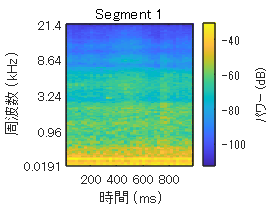

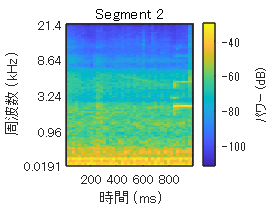

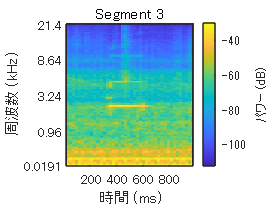

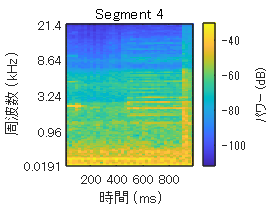

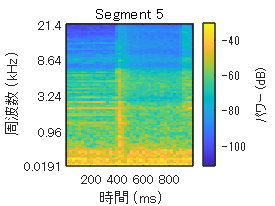

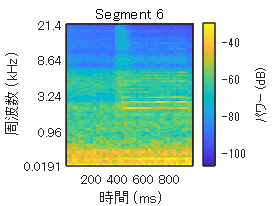


%% 
% Call <docid:audio_ref#mw_a427bc3f-f73e-448b-896a-65ddbb3c26fa |reset|> to 
% return the datastore to its initial condition.

reset(adsTrain)

%% Feature Extraction for CNN
% Each audio clip in the dataset consists of 10 seconds of stereo
% (left-right) audio. The feature extraction pipeline and the CNN
% architecture in this example are based on [3]. Hyperparameters for the
% feature extraction, the CNN architecture, and the training options were
% modified from the original paper using a systematic hyperparameter
% optimization workflow. 
%
% First, convert the audio to mid-side encoding. [3] suggests that mid-side
% encoded data provides better spatial information that the CNN can use to
% identify moving sources (such as a train moving across an acoustic
% scene).

dataMidSide = [sum(data,2),data(:,1)-data(:,2)];

%% 
% Divide the signal into one-second segments with overlap. The final
% system uses a probability-weighted average on the one-second segments to
% predict the scene for each 10-second audio clip in the test set. Dividing
% the audio clips into one-second segments makes the network easier to
% train and helps prevent overfitting to specific acoustic events in the
% training set. The overlap helps to ensure all combinations of features
% relative to one another are captured by the training data. It also
% provides the system with additional data that can be mixed uniquely
% during augmentation.

segmentLength = 1;
segmentOverlap = 0.5;

[dataBufferedMid,~] = buffer(dataMidSide(:,1),round(segmentLength*fs),round(segmentOverlap*fs),'nodelay');
[dataBufferedSide,~] = buffer(dataMidSide(:,2),round(segmentLength*fs),round(segmentOverlap*fs),'nodelay');
dataBuffered = zeros(size(dataBufferedMid,1),size(dataBufferedMid,2)+size(dataBufferedSide,2));
dataBuffered(:,1:2:end) = dataBufferedMid;
dataBuffered(:,2:2:end) = dataBufferedSide;

%% 
% Use <docid:audio_ref#mw_1bb316de-8018-4365-a351-73374473237f
% |melSpectrogram|> to transform the data into a compact frequency-domain
% representation. Define parameters for the mel spectrogram as suggested by
% [3].

windowLength = 2048;
samplesPerHop = 1024;
samplesOverlap = windowLength - samplesPerHop;
fftLength = 2*windowLength;
numBands = 128;

%% 
% |melSpectrogram| operates along channels independently. To optimize
% processing time, call |melSpectrogram| with the entire buffered signal.

spec = melSpectrogram(dataBuffered,fs, ...
    'Window',hamming(windowLength,'periodic'), ...
    'OverlapLength',samplesOverlap, ...
    'FFTLength',fftLength, ...
    'NumBands',numBands);

%% 
% Convert the mel spectrogram into the logarithmic scale.

spec = log10(spec+eps);

%% 
% Reshape the array to dimensions (Number of bands)-by-(Number of
% hops)-by-(Number of channels)-by-(Number of segments). When you feed an
% image into a neural network, the first two dimensions are the height and
% width of the image, the third dimension is the channels, and the fourth
% dimension separates the individual images.

X = reshape(spec,size(spec,1),size(spec,2),size(data,2),[]);

%% 
% Call |melSpectrogram| without output arguments to plot the mel
% spectrogram of the mid channel for the first six of the one-second
% increments.

for channel = 1:2:11
    figure
    melSpectrogram(dataBuffered(:,channel),fs, ...
        'Window',hamming(windowLength,'periodic'), ...
        'OverlapLength',samplesOverlap, ...
        'FFTLength',fftLength, ...
        'NumBands',numBands);
    title(sprintf('Segment %d',ceil(channel/2))) 
end


%%
% The helper function |HelperSegmentedMelSpectrograms| performs the feature
% extraction steps outlined above.


%% 
% To speed up processing, extract mel spectrograms of all audio files in
% the datastores using <docid:matlab_ref#bvaomuj-1 |tall|> arrays. Unlike
% in-memory arrays, tall arrays remain unevaluated until you request that
% the calculations be performed using the <docid:matlab_ref#bvaolov
% |gather|> function. This deferred evaluation enables you to work quickly
% with large data sets. When you eventually request the output using
% |gather|, MATLAB combines the queued calculations where possible and
% takes the minimum number of passes through the data. If you have Parallel
% Computing Toolbox(TM), you can use tall arrays in your local MATLAB
% session, or on a local parallel pool. You can also run tall array
% calculations on a cluster if you have MATLAB(R) Parallel Server(TM)
% installed.
%
% If you do not have Parallel Computing Toolbox(TM), the code in this
% example still runs.

train_set_tall = tall(adsTrain);
xTrain = cellfun(@(x)HelperSegmentedMelSpectrograms(x,fs, ...
    'SegmentLength',segmentLength, ...
    'SegmentOverlap',segmentOverlap, ...
    'WindowLength',windowLength, ...
    'HopLength',samplesPerHop, ...
    'NumBands',numBands, ...
    'FFTLength',fftLength), ...
    train_set_tall, ...
    'UniformOutput',false);
xTrain = gather(xTrain);

ローカル MATLAB セッション を使用して tall 式を評価中:
- パス 1/1: 1 分 19 秒 で完了
1 分 20 秒 で評価が完了しました


xTrain = cat(4,xTrain{:});

test_set_tall = tall(adsTest);
xTest = cellfun(@(x)HelperSegmentedMelSpectrograms(x,fs, ...
    'SegmentLength',segmentLength, ...
    'SegmentOverlap',segmentOverlap, ...
    'WindowLength',windowLength, ...
    'HopLength',samplesPerHop, ...
    'NumBands',numBands, ...
    'FFTLength',fftLength), ...
    test_set_tall, ...
    'UniformOutput',false);
xTest = gather(xTest);

ローカル MATLAB セッション を使用して tall 式を評価中:
- パス 1/1: 13 秒 で完了
13 秒 で評価が完了しました


xTest = cat(4,xTest{:});

%% 
% Replicate the labels of the training set so that they are in one-to-one
% correspondence with the segments.

numSegmentsPer10seconds = size(dataBuffered,2)/2;
yTrain = repmat(adsTrain.Labels,1,numSegmentsPer10seconds)';
yTrain = yTrain(:);

%{
%% Data Augmentation for CNN
% The DCASE 2017 dataset contains a relatively small number of acoustic
% recordings for the task, and the development set and evaluation set were
% recorded at different specific locations. As a result, it is easy to
% overfit to the data during training. One popular method to reduce
% overfitting is _mixup_. In mixup, you augment your dataset by mixing the
% features of two different classes. When you mix the features, you mix the
% labels in equal proportion. That is:
% 
% $$\begin{array}{l}\tilde{\mathrm{x}} =\lambda {\mathrm{x}}_i +\left(1-\lambda 
% \right){\mathrm{x}}_j \\\tilde{y} =\lambda y_i +\left(1-\lambda\right)y_j \end{array}$$
% 
% Mixup was reformulated by [2] as labels drawn from a probability
% distribution instead of mixed labels. The implementation of mixup in this
% example is a simplified version of mixup: each spectrogram is mixed with
% a spectrogram of a different label with lambda set to 0.5. The
% original and mixed datasets are combined for training.

xTrainExtra = xTrain;
yTrainExtra = yTrain;
lambda = 0.5;
for i = 1:size(xTrain,4)
    
    % Find all available spectrograms with different labels.
    availableSpectrograms = find(yTrain~=yTrain(i));
    
    % Randomly choose one of the available spectrograms with a different label.
    numAvailableSpectrograms = numel(availableSpectrograms);
    idx = randi([1,numAvailableSpectrograms]);
    
    % Mix.
    xTrainExtra(:,:,:,i) = lambda*xTrain(:,:,:,i) + (1-lambda)*xTrain(:,:,:,availableSpectrograms(idx));
    
    % Specify the label as randomly set by lambda.
    if rand > lambda
        yTrainExtra(i) = yTrain(availableSpectrograms(idx));
    end
end
xTrain = cat(4,xTrain,xTrainExtra);
yTrain = [yTrain;yTrainExtra];

%%
% Call |summary| to display the distribution of labels for the augmented
% training set.

summary(yTrain)
%}

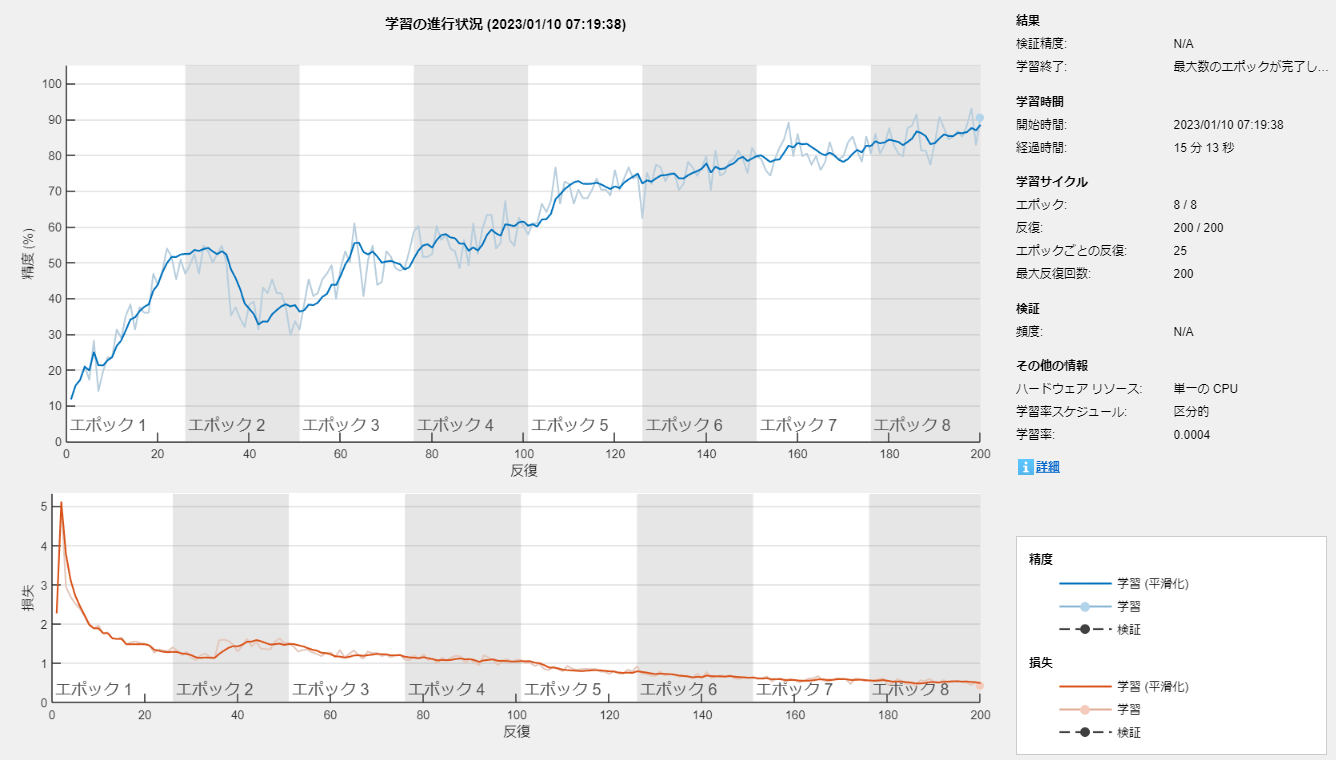


%% Define and Train CNN
%
% Define the CNN architecture. This architecture is based on [1] and
% modified through trial and error. See
% <docid:nnet_ug#mw_25a9e4c2-614f-48b9-97e2-bbdd7aaf906f List of Deep
% Learning Layers> to learn more about deep learning layers available in
% MATLAB(R).

imgSize = [size(xTrain,1),size(xTrain,2),size(xTrain,3)];
numF = 32;
layers = [ ...
    imageInputLayer(imgSize)
    
    batchNormalizationLayer
    
    convolution2dLayer(3,numF,'Padding','same')
    batchNormalizationLayer
    reluLayer
    convolution2dLayer(3,numF,'Padding','same')
    batchNormalizationLayer
    reluLayer 
    
    maxPooling2dLayer(3,'Stride',2,'Padding','same')

    convolution2dLayer(3,2*numF,'Padding','same')
    batchNormalizationLayer
    reluLayer
    convolution2dLayer(3,2*numF,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(3,'Stride',2,'Padding','same')
    
    convolution2dLayer(3,4*numF,'Padding','same')
    batchNormalizationLayer
    reluLayer
    convolution2dLayer(3,4*numF,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(3,'Stride',2,'Padding','same')
    
    convolution2dLayer(3,8*numF,'Padding','same')
    batchNormalizationLayer
    reluLayer
    convolution2dLayer(3,8*numF,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    globalAveragePooling2dLayer
    
    dropoutLayer(0.5)
    
    fullyConnectedLayer(7)
    softmaxLayer
    classificationLayer];

%% 
% Define <docid:nnet_ref#bu59f0q |traingOptions|> for the CNN. These
% options are based on [3] and modified through a systematic hyperparameter
% optimization workflow.

miniBatchSize = 128;
tuneme = 128;
lr = 0.05*miniBatchSize/tuneme;
options = trainingOptions('adam', ...
    'InitialLearnRate',lr, ...
    'MiniBatchSize',miniBatchSize, ...
    'L2Regularization',0.005, ...
    'MaxEpochs',8, ...
    'Shuffle','every-epoch', ...
    'Plots','training-progress', ...
    'Verbose',false, ...
    'LearnRateSchedule','piecewise', ...
    'LearnRateDropPeriod',2, ...
    'LearnRateDropFactor',0.2);

%% 
% Call <docid:nnet_ref#bu6sn4c |trainNetwork|> to train the network.

trainedNet = trainNetwork(xTrain,yTrain,layers,options);

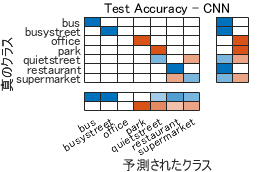


%% Evaluate CNN
% Call <docid:nnet_ref#mw_0a51db93-cccf-4b2f-ae4c-6724cbf5ec46 |predict|>
% to predict responses from the trained network using the held-out test
% set.

cnnResponsesPerSegment = predict(trainedNet,xTest);

%% 
% Average the responses over each 10-second audio clip.

classes = trainedNet.Layers(end).Classes;
numFiles = numel(adsTest.Files);

counter = 1;
cnnResponses = zeros(numFiles,numel(classes));
for channel = 1:numFiles
    cnnResponses(channel,:) = sum(cnnResponsesPerSegment(counter:counter+numSegmentsPer10seconds-1,:),1)/numSegmentsPer10seconds;
    counter = counter + numSegmentsPer10seconds;
end

%%
% For each 10-second audio clip, choose the maximum of the predictions,
% then map it to the corresponding predicted location.

[~,classIdx] = max(cnnResponses,[],2);
cnnPredictedLabels = classes(classIdx);

%% 
% Call <docid:nnet_ref#mw_b571feea-6af0-489f-b52c-a4b5141ac550
% |confusionchart|> to visualize the accuracy on the test set. Return the
% average accuracy to the Command Window.

figure('Units','normalized','Position',[0.2 0.2 0.5 0.5])
cm = confusionchart(adsTest.Labels,cnnPredictedLabels,'title','Test Accuracy - CNN');
cm.ColumnSummary = 'column-normalized';
cm.RowSummary = 'row-normalized';


fprintf('Average accuracy of CNN = %0.2f\n',mean(adsTest.Labels==cnnPredictedLabels)*100)

Average accuracy of CNN = 57.14



%% Feature Extraction for Ensemble Classifier
% Wavelet scattering has been shown in [4] to provide a good representation
% of acoustic scenes. Define a
% <docid:wavelet_ref#mw_a0dd2386-66f5-4c0b-b96d-7ae0ba327cd1
% |waveletScattering|> object. The invariance scale and quality factors
% were determined through trial and error.

sf = waveletScattering('SignalLength',size(data,1), ...
                       'SamplingFrequency',fs, ...
                       'InvarianceScale',0.75, ...
                       'QualityFactors',[4 1]);

%% 
% Convert the audio signal to mono, and then call
% <docid:wavelet_ref#mw_edb9d918-ed3b-469f-8cb0-5e6cbd25f87c
% |featureMatrix|> to return the scattering coefficients for the scattering
% decomposition framework, |sf|.

dataMono = mean(data,2);
scatteringCoeffients = featureMatrix(sf,dataMono,'Transform','log');

%% 
% Average the scattering coefficients over the 10-second audio clip.

featureVector = mean(scatteringCoeffients,2);
fprintf('Number of wavelet features per 10-second clip = %d\n',numel(featureVector))

Number of wavelet features per 10-second clip = 286



%% 
% The helper function |HelperWaveletFeatureVector| performs the above steps.
% Use a <docid:matlab_ref#bvaomuj-1 |tall|> array with
% <docid:matlab_ref#bsz9tpz |cellfun|> and |HelperWaveletFeatureVector| to
% parallelize the feature extraction. Extract wavelet feature vectors for
% the train and test sets.

scatteringTrain = cellfun(@(x)HelperWaveletFeatureVector(x,sf),train_set_tall,'UniformOutput',false);
xTrain = gather(scatteringTrain);

ローカル MATLAB セッション を使用して tall 式を評価中:
- パス 1/1: 3 分 49 秒 で完了
3 分 49 秒 で評価が完了しました


xTrain = cell2mat(xTrain')';
   
scatteringTest = cellfun(@(x)HelperWaveletFeatureVector(x,sf),test_set_tall,'UniformOutput',false);
xTest = gather(scatteringTest);

ローカル MATLAB セッション を使用して tall 式を評価中:
- パス 1/1: 57 秒 で完了
57 秒 で評価が完了しました


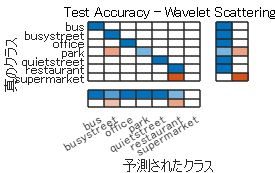

xTest = cell2mat(xTest')';

%% Define and Train Ensemble Classifier
% Use |fitcensemble| to create a trained classification ensemble model
% (|ClassificationEnsemble|).

subspaceDimension = min(150,size(xTrain,2) - 1);
numLearningCycles = 30;
classificationEnsemble = fitcensemble(xTrain,adsTrain.Labels, ...
    'Method','Subspace', ...
    'NumLearningCycles',numLearningCycles, ...
    'Learners','discriminant', ...
    'NPredToSample',subspaceDimension, ...
    'ClassNames',removecats(unique(adsTrain.Labels)));

%% Evaluate Ensemble Classifier
% For each 10-second audio clip, call |predict| to return the labels and
% the weights, then map it to the corresponding predicted location. Call
% <docid:nnet_ref#mw_b571feea-6af0-489f-b52c-a4b5141ac550 |confusionchart|>
% to visualize the accuracy on the test set. Print the average.

[waveletPredictedLabels,waveletResponses] = predict(classificationEnsemble,xTest);

figure('Units','normalized','Position',[0.2 0.2 0.5 0.5])
cm = confusionchart(adsTest.Labels,waveletPredictedLabels,'title','Test Accuracy - Wavelet Scattering');
cm.ColumnSummary = 'column-normalized';
cm.RowSummary = 'row-normalized';


fprintf('Average accuracy of classifier = %0.2f\n',mean(adsTest.Labels==waveletPredictedLabels)*100)

Average accuracy of classifier = 78.57


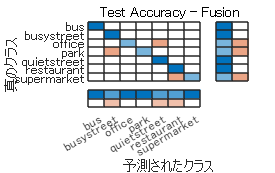


%% Apply Late Fusion
% For each 10-second clip, calling predict on the wavelet classifier and
% the CNN returns a vector indicating the relative confidence in their
% decision. Multiply the |waveletResponses| with the |cnnResponses| to
% create a late fusion system.

fused = waveletResponses .* cnnResponses;
[~,classIdx] = max(fused,[],2);

predictedLabels = classes(classIdx);

%% Evaluate Late Fusion
% Call |confusionchart| to visualize the fused classification accuracy.
% Print the average accuracy to the Command Window.

figure('Units','normalized','Position',[0.2 0.2 0.5 0.5])
cm = confusionchart(adsTest.Labels,predictedLabels,'title','Test Accuracy - Fusion');
cm.ColumnSummary = 'column-normalized';
cm.RowSummary = 'row-normalized';


fprintf('Average accuracy of fused models = %0.2f\n',mean(adsTest.Labels==predictedLabels)*100)

Average accuracy of fused models = 78.57



%% References
% [1] A. Mesaros, T. Heittola, and T. Virtanen. Acoustic Scene
% Classification: an Overview of DCASE 2017 Challenge Entries. In proc.
% International Workshop on Acoustic Signal Enhancement, 2018.
% 
% [2] Huszar, Ferenc. "Mixup: Data-Dependent Data Augmentation." InFERENCe.
% November 03, 2017. Accessed January 15, 2019.
% https://www.inference.vc/mixup-data-dependent-data-augmentation/.
% 
% [3] Han, Yoonchang, Jeongsoo Park, and Kyogu Lee. "Convolutional neural
% networks with binaural representations and background subtraction for
% acoustic scene classification." the Detection and Classification of
% Acoustic Scenes and Events (DCASE) (2017): 1-5.
% 
% [4] Lostanlen, Vincent, and Joakim Anden. Binaural scene classification
% with wavelet scattering. Technical Report, DCASE2016 Challenge, 2016.
% 
% [5] A. J. Eronen, V. T. Peltonen, J. T. Tuomi, A. P. Klapuri, S.
% Fagerlund, T. Sorsa, G. Lorho, and J. Huopaniemi, "Audio-based context
% recognition," IEEE Trans. on Audio, Speech, and Language Processing, vol
% 14, no. 1, pp. 321-329, Jan 2006.
%
% [6] <https://zenodo.org/record/400515 TUT Acoustic scenes 2017,
% Development dataset>
%
% [7] <https://zenodo.org/record/1040168 TUT Acoustic scenes 2017,
% Evaluation dataset>

%% Appendix -- Supporting Functions

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%HelperSegmentedMelSpectrograms

function X = HelperSegmentedMelSpectrograms(x,fs,varargin)
% Copyright 2019 The MathWorks, Inc.
p = inputParser;
addParameter(p,'WindowLength',1024);
addParameter(p,'HopLength',512);
addParameter(p,'NumBands',128);
addParameter(p,'SegmentLength',1);
addParameter(p,'SegmentOverlap',0);
addParameter(p,'FFTLength',1024);
parse(p,varargin{:})
params = p.Results;

x = [sum(x,2),x(:,1)-x(:,2)];
x = x./max(max(x));

[xb_m,~] = buffer(x(:,1),round(params.SegmentLength*fs),round(params.SegmentOverlap*fs),'nodelay');
[xb_s,~] = buffer(x(:,2),round(params.SegmentLength*fs),round(params.SegmentOverlap*fs),'nodelay');
xb = zeros(size(xb_m,1),size(xb_m,2)+size(xb_s,2));
xb(:,1:2:end) = xb_m;
xb(:,2:2:end) = xb_s;

spec = melSpectrogram(xb,fs, ...
    'Window',hamming(params.WindowLength,'periodic'), ...
    'OverlapLength',params.WindowLength - params.HopLength, ...
    'FFTLength',params.FFTLength, ...
    'NumBands',params.NumBands, ...
    'FrequencyRange',[0,floor(fs/2)]);
spec = log10(spec+eps);

X = reshape(spec,size(spec,1),size(spec,2),size(x,2),[]);
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%HelperWaveletFeatureVector
function features = HelperWaveletFeatureVector(x,sf)
x = mean(x,2);
features = featureMatrix(sf,x,'Transform','log');
features = mean(features,2);
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%
% Copyright 2019 The MathWorks, Inc.